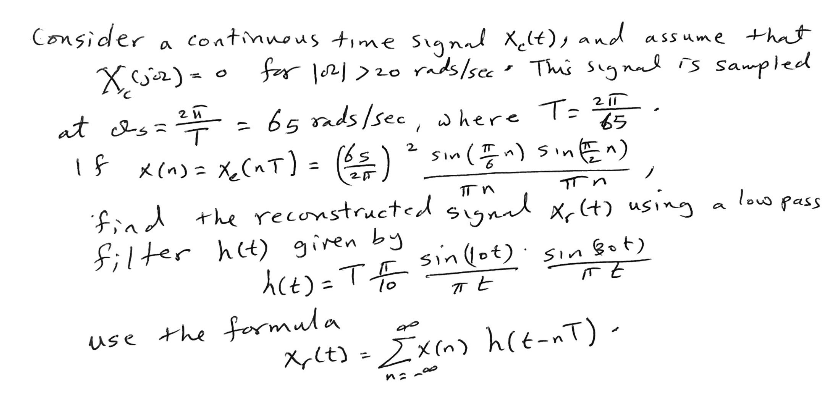

The sampling frequency is deffinitely more than twice the maximum frequency of x, so it can be sampled properly.

% Generate plot of x
T = 2*pi/65;
n = -10:T:10;

% generate plot of x(n)
x = ((1/T)^2)*(sin(pi*n/6).*sin(pi*n/2))./((pi*n).^2);
% replace all NaN values with the value of x when n is zero
x(isnan(x)) = 4225/(48*pi^2)

x =    -0.0000   -0.0149   -0.0308   -0.0471   -0.0635   -0.0794   -0.0942   -0.1074   -0.1185   -0.1271   -0.1327   -0.1350   -0.1339   -0.1293   -0.1212   -0.1097   -0.0951   -0.0779   -0.0584   -0.0374   -0.0154    0.0069    0.0287    0.0494    0.0682    0.0846    0.0980    0.1081    0.1144    0.1170    0.1157    0.1109    0.1028    0.0920    0.0790    0.0648    0.0500    0.0357    0.0226    0.0119    0.0042    0.0003    0.0009    0.0063    0.0168    0.0323    0.0526    0.0770    0.1048    0.1348


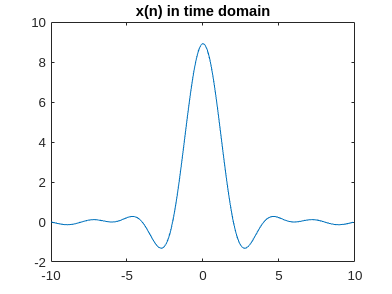

plot(n, x)
title("x(n) in time domain")


%Generate Plot of h
h = (pi*T/10)*(sin(10*n)/(pi*n)).*(sin(30*n)./(pi*n));
% This was manually calculated because I couldn't figure out how to convert this function to matlab's sinc() function
h(isnan(h)) = 12/13 % the value of h when n is zero. 

h = 1.0e-03 *

    0.0008   -0.0008    0.0007   -0.0006    0.0005   -0.0003    0.0001    0.0001   -0.0003    0.0005   -0.0006    0.0008   -0.0008    0.0009   -0.0009    0.0008   -0.0007    0.0005   -0.0004    0.0001    0.0001   -0.0003    0.0005   -0.0007    0.0009   -0.0010    0.0010   -0.0010    0.0010   -0.0008    0.0006   -0.0004    0.0002    0.0001   -0.0004    0.0006   -0.0009    0.0011   -0.0012    0.0012   -0.0012    0.0011   -0.0010    0.0008   -0.0005    0.0002    0.0001   -0.0005    0.0008   -0.0011


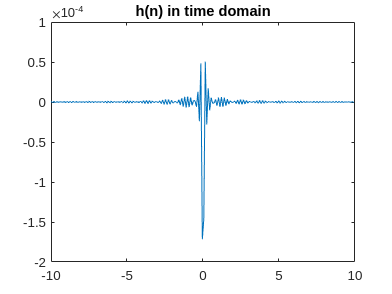

plot(n, h)
title("h(n) in time domain")

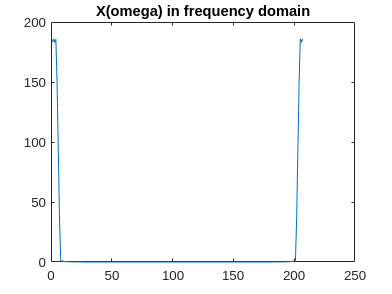


% Take the fft of h and x and plot them
X = fft(x);
H = fft(h);
plot(abs(X))
title("X(omega) in frequency domain")

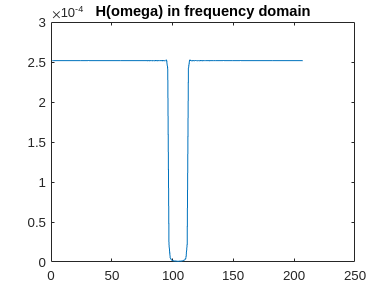

plot(abs(H))
title("H(omega) in frequency domain")

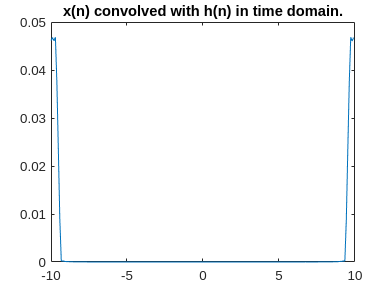


% convolve and plot the frequency result
X_r = X.*H;
plot(n,abs(X_r))
title("x(n) convolved with h(n) in time domain.")

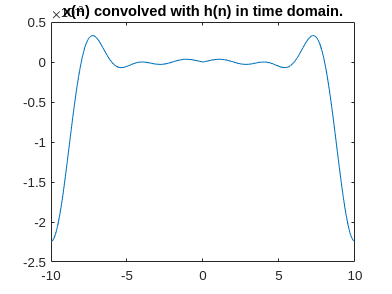

% plot the convolution in the time domain
x_r = ifft(X_r);
plot(n,x_r)
title("x(n) convolved with h(n) in time domain.")